# Incapacity Episode Analysis (2022-now)

## Data Selection

currentYear = year(datetime("now"));
yearStudy = double( "2023");
monthsValidDict = dictionary(2022:2023,{7:10,[2 3 4 5 6 7]}); % months with 
monthsStudy = monthsValidDict{yearStudy}; % use all valid months by default
numMonthsStudy = numel(monthsStudy);


## Data Access & Cleaning

#### Read year of interest from data table

TYear = readtable(fullfile('data','Episodes.xlsx'),'Sheet',string(yearStudy) + " Episodes",'TextType','string');

#### Crete cleaned/decorated study table for downstream analysis

% Crate study table with missing durations removed 
TStudy = TYear(~ismissing(TYear.Duration),:);

% Convert Duration variable to MATLAB duration type
durationTimestamp = datetime(datevec(TStudy.Duration)); %represent duration variable as a datetime timestamp
referenceTimestamp = datetime(zeros(1,6)); % start of day on first date

durationVar = durationTimestamp - referenceTimestamp;
TStudy.Duration = durationVar; 

% Remove months not under study
TStudy = TStudy(ismember(month(TStudy.Date),monthsStudy),:);

% Add categorical month variable
monthVec = categorical(datetime(2022,month(TStudy.Date),1,'Format','MMMM'),'Ordinal',true); %awkward: lots of steps from month numbers to month categorical
TStudy = addvars(TStudy,monthVec,'NewVariableNames',"Month");
TStudy.Month = removecats(TStudy.Month);


## Current Year Visualization

#### Visualize episodes across all study months with a swarm chart

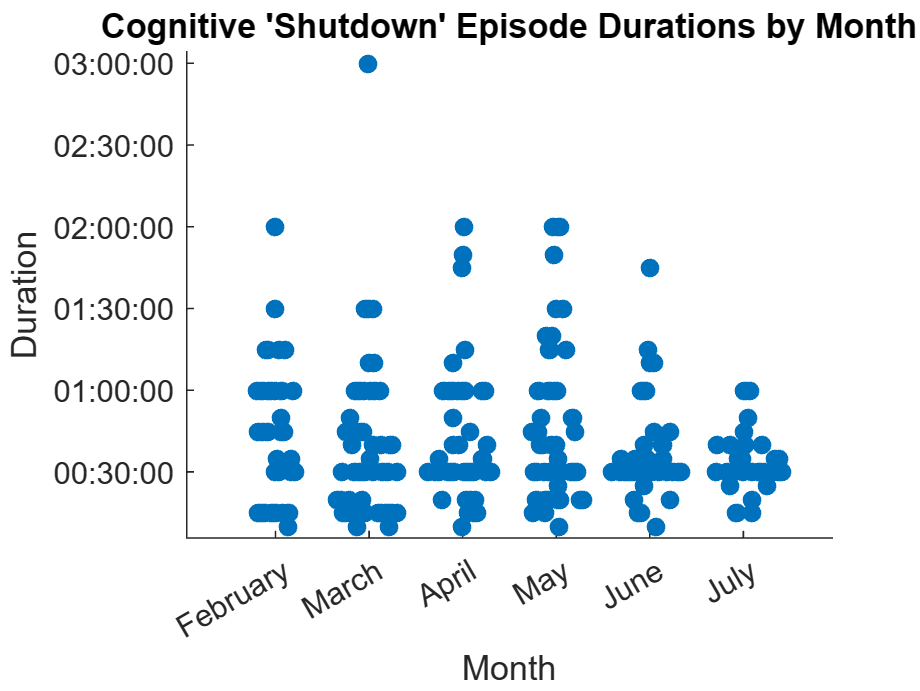


durationsByMonth = cell(1,numMonthsStudy);
TSwarm = TStudy(1,:); 
TSwarm(1,:) = [];
for idx = 1:numel(monthsStudy)
    m = monthsStudy(idx);
    TSwarm = [TSwarm;TStudy(month(TStudy.Date) == m,:)]; %#ok<AGROW> 
end
swarmchart(TStudy,"Month","Duration","filled");
title("Cognitive 'Shutdown' Episode Durations by Month");

#### Compute summary statistics of episodes during each month

[medianDuration,meanDuration, numEpisodesByMonth, numDaysTracked] = deal(zeros(numel(monthsStudy),1));

for idx = 1:numel(monthsStudy)
    m = monthsStudy(idx);

    summaryStruct = summary(TStudy(month(TStudy.Date) == m,:));
    s = summaryStruct.Duration;
    medianDuration(idx) = minutes(s.Median);
    numEpisodesByMonth(idx) = prod(s.Size);

    numDaysTracked(idx) = days(summaryStruct.Date.Max - summaryStruct.Date.Min) + 1;

    meanDuration(idx) = mean(minutes(TStudy{month(TStudy.Date) == m,"Duration"}));
    
    assert(medianDuration(idx) == median(minutes(TStudy{month(TStudy.Date) == m,"Duration"})));
end

#### Plot summary statistics of episodes during each month

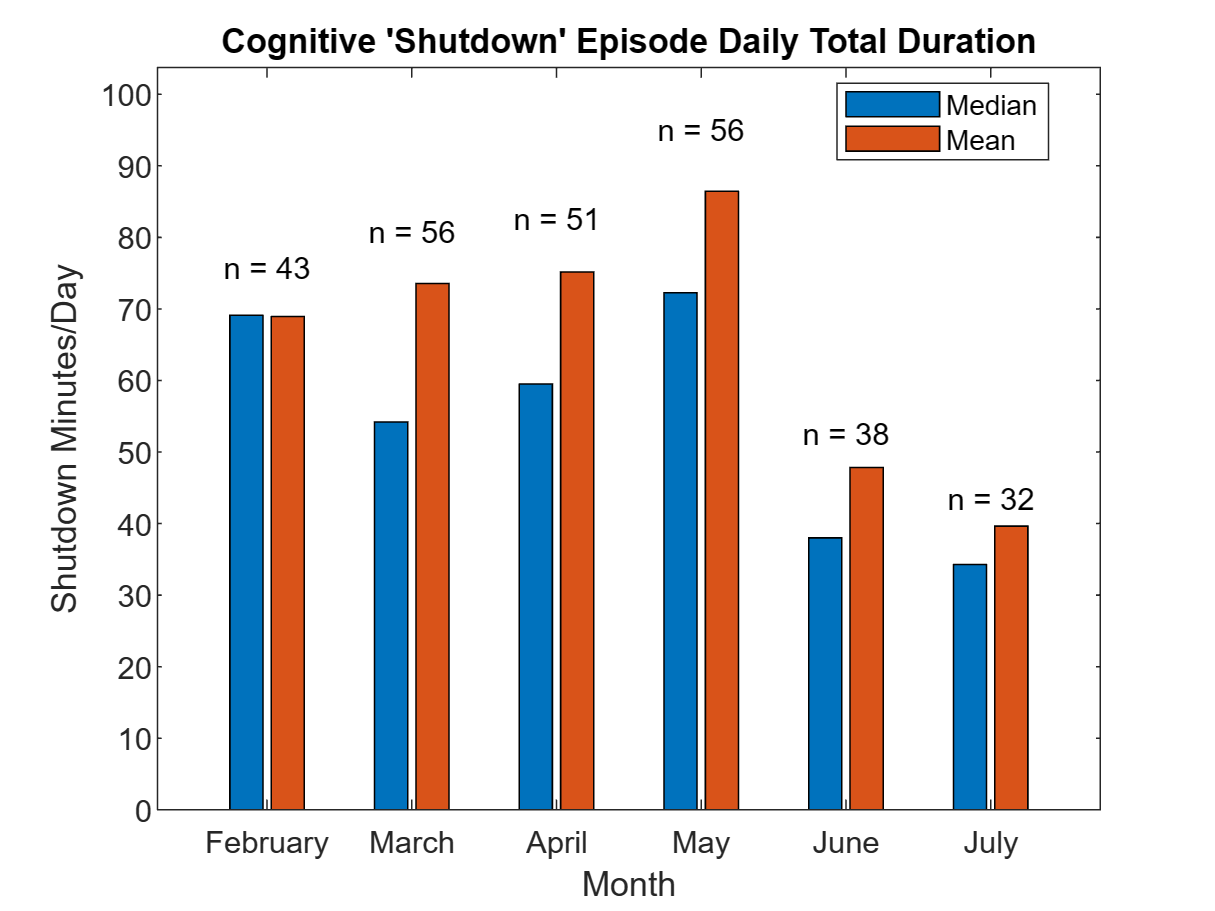


daysInMonth = zeros(numMonthsStudy,1);

for idx = 1:numMonthsStudy
    
    if month(datetime("now")) == monthsStudy(idx) % mid-month analysis
        daysInMonth(idx) = numDaysTracked(idx);
    else
        calendar_ = calendar(yearStudy,monthsStudy(idx));
        daysInMonth(idx) = max(calendar_,[],'all');
    end
end

monthsStudy_ = unique(TStudy.Month);

bar(monthsStudy_,numEpisodesByMonth.*[medianDuration meanDuration]./daysInMonth);

dailyShutdownMinsMean = numEpisodesByMonth.*meanDuration./daysInMonth;
for idx = 1:numMonthsStudy
        text(monthsStudy_(idx),dailyShutdownMinsMean(idx)*1.1,"n = " + string(numEpisodesByMonth(idx)),'HorizontalAlignment','center');
end

ylim([0 max(dailyShutdownMinsMean*1.2)]);
xlabel("Month");
ylabel("Shutdown Minutes/Day");
title("Cognitive 'Shutdown' Episode Daily Total Duration")
legend(["Median" "Mean"],"Location","best");

## Last Month Visualization

#### Visualize episodes during a specific month 

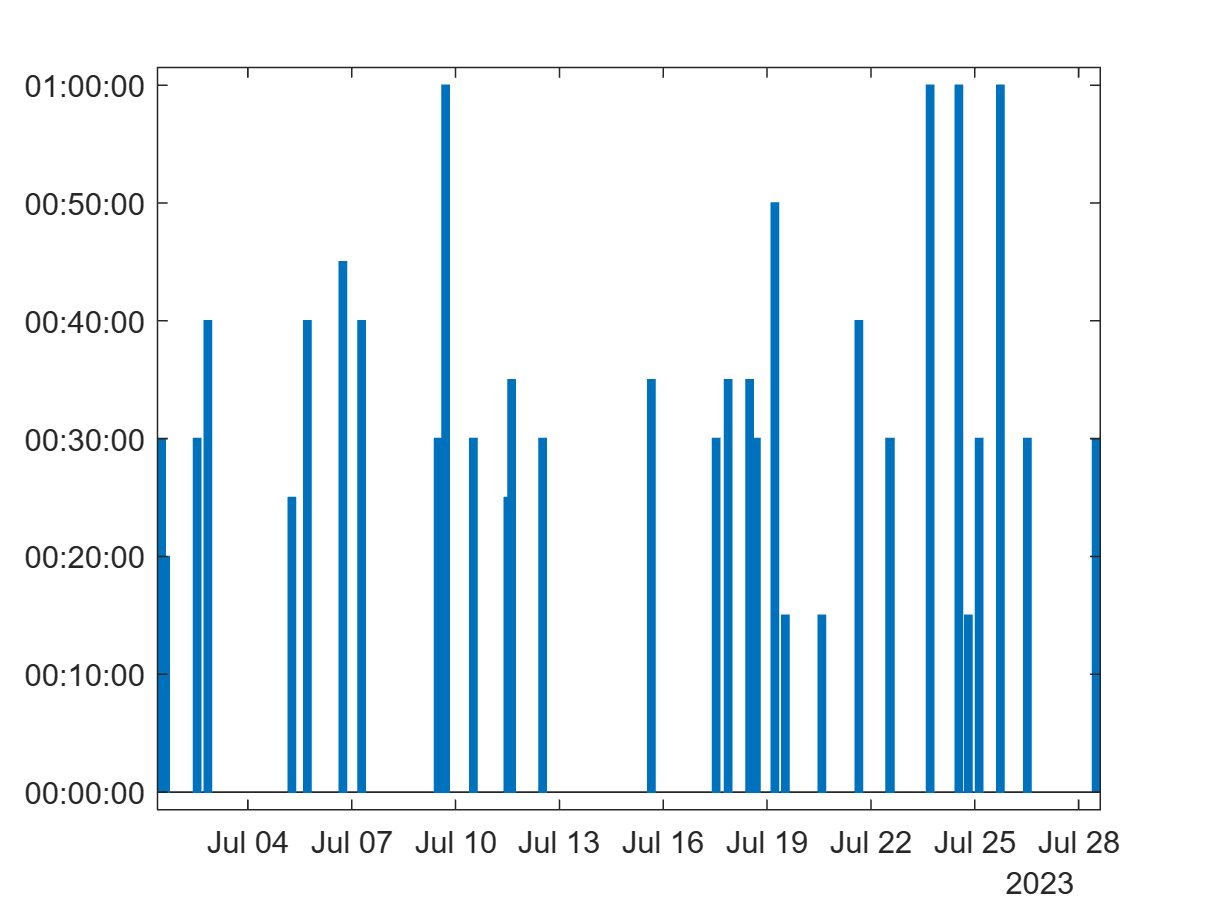

%monthViz =7;
monthViz = monthsStudy(end); % most recent month; comment out to select with control above

TViz = TStudy(month(TStudy.Date) == monthViz,:);

hChart = bar(TViz.Timestamp,TViz.Duration,'BarWidth',10);
hChart.EdgeColor = hChart.FaceColor;